# Waveform Design for a Dual-Function MIMO RadCom System

This example shows how to design a set of waveforms for a dual-function multiple-input-multiple-output (MIMO) radar-communication (RadCom) system. It then uses the designed waveforms to simulate a RadCom system that can detect targets in range and azimuth, as well as transmit data to multiple downlink users.

## Joint Radar-Communication

Radar systems require large bandwidth to achieve high resolution while communication systems require large bandwidth to achieve high data rates. With a growing number of connected devices, the frequency spectrum becomes increasingly congested. To make the frequency spectrum usage more efficient the radar and the communication communities have recently proposed a host of approaches for radar-communication coexistence. These approaches range from non-cooperative spectrum sharing that rely on spectrum sensing and dynamic spectrum access to joint RadCom systems optimized for both functions [1]. 

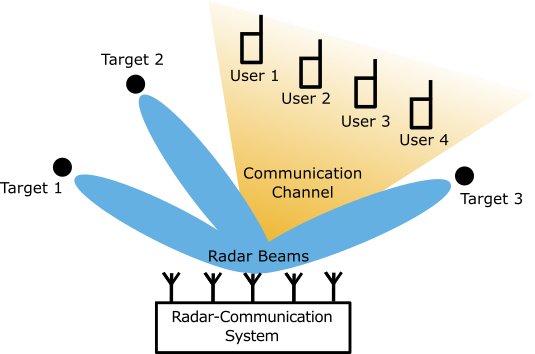

This example shows how to design a set of dual-function waveforms for a joint RadCom system. This RadCom system uses a phased array to facilitate MIMO communication. It also takes advantage of waveform diversity to achieve good radar performance. Assume the carrier frequency is 6GHz, the peak transmit power is 0.5 MW, and the same uniform linear array (ULA) is used for transmitting and receiving. Create a ULA with $N$ = 16 isotropic antenna elements spaced half of a wavelength apart. 

rng('default');                     % Set random number generator for reproducibility

fc = 6e9;                           % Carrier frequency (Hz)
Pt = 0.5e6;                         % Peak transmit power (W)
lambda = freq2wavelen(fc);          % Wavelength (m)

N = 16;                             % Number of array elements
d = 0.5*lambda;                     % Array element spacing (m)

% Use isotropic antenna elements
element = phased.IsotropicAntennaElement('BackBaffled', true);
array = phased.ULA('Element', element, 'NumElements', N, 'ElementSpacing', d, 'ArrayAxis', 'y');

Since the objectives of the radar and the communication components of the RadCom system are fundamentally different, each component imposes different requirements on the transmitted waveforms.

### Objective of the Radar Component

The goal of the Rad component is to form multiple transmit beams in the directions of targets of interest (for example, the tracker subsystem can provide predicted target positions).

Create a desired transmit beam pattern with 10 degree beams pointing at each target. 

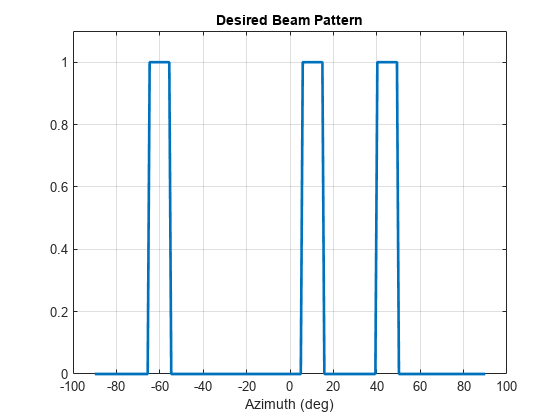

% Three targets of interest
tgtAz = [-60 10 45];                % Azimuths of the targets of interest
tgtRng = [5.31e3, 6.23e3, 5.7e3];   % Ranges of the targets of interest

ang = linspace(-90, 90, 200);       % Grid of azimuth angles
beamwidth = 10;                     % Desired beamwidth

% Desired beam pattern
idx = false(size(ang));
for i = 1:numel(tgtAz)
    idx = idx | ang >= tgtAz(i)-beamwidth/2 & ang <= tgtAz(i)+beamwidth/2;
end

Bdes = zeros(size(ang));
Bdes(idx) = 1;

figure
plot(ang, Bdes, 'LineWidth', 2)
xlabel('Azimuth (deg)')
title('Desired Beam Pattern')
grid on
ylim([0 1.1])

### Objective of the Communication Component

The goal of the Com component is to transmit communication symbols to downlink users. Let there be `K`=4 single-antenna users and a communication message consisting of `M`=30 symbols. Create a `K`-by-`M` matrix `S` of QPSK symbols that represents the desired communication message.

K = 4;                              % Number of communication users
M = 30;                             % Number of communication symbols

Q = 4;
data = randi([0 Q-1], K, M);        % Binary data
S = pskmod(data, Q, pi/Q);          % QPSK symbols

Create a `K`-by-`N` matrix `H` that models a scattering channel between `N` RadCom antenna elements and `K` downlink users. This matrix is typically assumed to be known to the RadCom system prior to the waveform design.

% User locations are random
txpos = [rand(1, K)*1.5e3; rand(1, K)*2.4e3 - 1.2e3; zeros(1, K)];

% Create a scattering channel matrix assuming 100 independent scatterers
numscat = 100;
rxpos = array.getElementPosition();    
H = scatteringchanmtx(rxpos, txpos, numscat).'

H =    6.9220 - 1.1247i   7.1017 - 0.9594i   7.1987 - 0.8061i   7.2116 - 0.6666i   7.1400 - 0.5421i   6.9853 - 0.4333i   6.7501 - 0.3404i   6.4382 - 0.2632i   6.0549 - 0.2010i   5.6067 - 0.1526i   5.1011 - 0.1165i   4.5465 - 0.0908i   3.9525 - 0.0733i   3.3289 - 0.0617i   2.6864 - 0.0536i   2.0357 - 0.0465i
 -10.6335 - 8.1281i  -9.9214 - 8.4327i  -9.1425 - 8.7545i  -8.3116 - 9.0850i  -7.4454 - 9.4151i  -6.5620 - 9.7352i  -5.6804 -10.0353i  -4.8206 -10.3055i  -4.0023 -10.5361i  -3.2454 -10.7180i  -2.5688 -10.8428i  -1.9903 -10.9031i  -1.5263 -10.8926i  -1.1909 -10.8064i  -0.9961 -10.6411i  -0.9511 -10.3950i
   4.5973 + 3.1755i   4.6600 + 3.4353i   4.7256 + 3.6782i   4.8029 + 3.9025i   4.9008 + 4.1061i   5.0280 + 4.2865i   5.1927 + 4.4408i   5.4020 + 4.5658i   5.6621 + 4.6581i   5.9779 + 4.7141i   6.3528 + 4.7302i   6.7885 + 4.7027i   7.2849 + 4.6283i   7.8401 + 4.5038i   8.4503 + 4.3264i   9.1098 + 4.0940i
  -3.2160 - 5.8685i  -3.3480 - 5.4857i  -3.5441 - 5.0363i  -3.8054 - 4.5215i  -4.

Next, the example will show how to create a set of radar waveforms that satisfy the radar objective and form the desired transmit beam pattern. It will then show how to embed the desired communication message into the synthesized waveforms. Finally, the example will model a transmission from the RadCom system. It will plot the resulting range-angle response and compute the symbol error rate to verify that the system is capable of performing both functions.

## MIMO Radar Waveform Synthesis

The Rad component of the RadCom system is a MIMO radar. Unlike a traditional phased array radar that transmits a scaled version of the same waveform from each antenna element, a MIMO radar utilizes waveform diversity and transmits $N$ different waveforms. These waveforms combine to form the transmit beam pattern. By adjusting the transmitted waveforms, a MIMO radar can dynamically adjust its transmit beam pattern.

Let an $N$-by-$M$ matrix ${\bf X}$ represent the transmitted waveforms such that the rows of ${\bf X}$ correspond to the $N$ antenna elements and the columns of ${\bf X}$ to $M$ subpulses. The resulting transmit beam pattern is [2]


$$B(\theta) = \frac{1}{4\pi}{\bf a}^H(\theta)\cdot{\bf R}\cdot{\bf a}(\theta)$$


where ${\bf a}(\theta)$ is the array steering vector, $\theta$ is the azimuth angle, and ${\bf R} = \frac{1}{M}{\bf X}{\bf X}^H$ is the waveform covariance matrix. This relationship shows that design of a transmit beam pattern for a MIMO radar is equivalent to designing the waveform covariance matrix. Therefore, the waveform design process can be broken into two steps. First, you find a covariance matrix that produces the desired beam pattern, and then synthesize the waveforms based on the found covariance matrix. Designing the covariance matrix first is much easier compared to selecting the waveforms directly, since typically $M\gg N$, and thus ${\bf R}$ has much fewer unknowns than ${\bf X}$. 

### From Beam Pattern to Covariance Matrix

Given a desired beam pattern $B_{des}(\theta)$, a waveform covariance matrix ${\bf R}$ can be found by minimizing the mean squared error between the desired and the actual beam pattern [2]


$$\min_{\bf_R} \int_{\theta} \left| B_{des}(\theta) - \frac{1}{4\pi}{\bf a}^H(\theta)\cdot{\bf R}\cdot{\bf a}(\theta)\right|^2cos(\theta)d\theta
$$


s.t. $diag({\bf R}) = \frac{P_t}{N}{\bf 1}
$


$${\bf R} \in \mathbb{S}_{+}^N$$


where $P_t$ is the total transmit power. The first constraint in this optimization problem requires that the diagonal elements of ${\bf R}$ are equal to $\frac{P_t}{N}$. This guarantees that each antenna element transmits equal power, and the total transmitted power is equal to $P_t$. The second constraint restricts ${\bf R}$ to the set of positive semidefinite matrices, which is a necessary requirement for a valid covariance matrix. Use the `helperMMSECovariance` helper function to solve this optimization problem for the desired beam pattern in `Bdes`. The solution is the optimal covariance matrix `Rmmse` that results in a beam pattern closest to the desired beam pattern in the minimum mean squared error (MMSE) sense.

% Normalize the antenna element positions by the wavelength
normalizedPos = rxpos/lambda;

% Solve the optimization problem to find the covariance matrix
Rmmse = helperMMSECovariance(normalizedPos, Bdes, ang);

% helperMMSECovariance returns a covariance matrix with 1s along the
% diagonal such that the total transmit power is equal to N. Renormalize
% the covariance matrix to make the total transmit power equal to Pt.
Rmmse = Rmmse*Pt/N;

% Matrix of steering vectors corresponding to the angles in the grid ang
A = steervec(normalizedPos, [ang; zeros(size(ang))]);

% Compute the resulting beam pattern given the found covariance matrix
Bmmse = abs(diag(A'*Rmmse*A))/(4*pi);

Compare the beam pattern obtained through the mean squared optimization with the desired beam pattern.

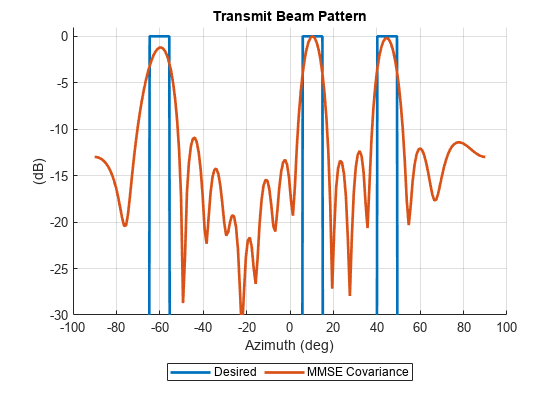

figure
hold on
plot(ang, pow2db(Bdes + eps), 'LineWidth', 2)
plot(ang, pow2db(Bmmse/max(Bmmse)), 'LineWidth', 2)

grid on
xlabel('Azimuth (deg)')
ylabel('(dB)')
legend('Desired', 'MMSE Covariance', 'Location', 'southoutside', 'Orientation', 'horizontal')
ylim([-30 1])
title('Transmit Beam Pattern')

The beam pattern obtained from the covariance matrix in `Rmmse` has three main lobes that match the main lobes of the desired beam pattern and correspond to the directions of the targets of interest. The resulting sidelobe level depends on the available aperture size.

### From Covariance Matrix to Waveform

Once the covariance matrix is known, the problem of synthesizing radar waveforms that produce the desired beam pattern reduces to the problem of finding a set of waveforms with a given covariance ${\bf R}$. But to be useful in practice these waveforms also must meet a number of constraints. For power-efficient transmission both radar and communication systems typically require the waveforms to have a constant modulus. Since, it might be numerically difficult to find a set of constant modulus waveforms with a given covariance matrix, the waveforms can be constrained in terms of the peak-to-average-power ratio (PAR) instead. The PAR for the $n$th transmitted waveform is


$$PAR_n=\frac{1}{P_n}max_m|X(n,m)|^2$$


where $P_n = \frac{1}{M}\sum_{m=1}^{M}|X(n,m)|^2$ is the average power, $n=1,2,\ldots.N$, and $m=1,2,\ldots,M$. Notice that the diagonal elements of the waveform covariance matrix $R(n,n)$ are equal to the average powers of the waveforms $P_n$. If each antenna element transmits equal power, and the total transmit power is $P_t$, then $P_n=\frac{P_t}{N}$. For a set of $N$ waveforms, the following low PAR constraint can be set


$$\begin{cases}
\begin{array}{||}
\frac{1}{M}\sum_{m=1}^{M}|X(n,m)|^2 = \frac{P_t}{N} && n=1,2,\ldots,N\\
|X(n,m)|^2\leq\eta \frac{P_t}{N} && \forall n,m \textrm{ and } \eta \in [1, M]
\end{array}
\end{cases}$$


This constraint requires that the average power of each waveform in the set is equal to the total power divided by the number of antenna elements and that the power for each subpulse does not exceed the average power by more than a factor of $\eta$. If $\eta$ is set to 1, the low PAR constraint becomes the constant modulus constraint.

In [3] the authors propose a cyclic algorithm (CA) for synthesizing waveforms given a desired covariance matrix such that the PAR constraint is satisfied. The helper function `helperCAWaveformSynthesis` implements a version of this algorithm described in [4] that also minimizes the autocorrelation sidelobes for each waveform. Set the parameter $\eta$ to 1.1 and use `helperCAWaveformSynthesis` to find a set of waveforms that have a covariance matrix equal to the optimal covariance matrix in `Rmmse`. Set the number of subpulses in the generated waveform to be equal to the number of symbols in the desired communication symbol matrix `S`.

eta = 1.1;                          % Parameter that controls low PAR constraint

% Find a set of waveform with the covariance equal to Rmmse using the
% cyclic algorithm. The length of each waveform is M.
Xca = helperCAWaveformSynthesis(Rmmse, M, eta);

% Covariance matrix of the computed waveforms
Rca = Xca*Xca'/M;

% The resulting beam pattern
Bca = abs(diag(A'*Rca*A))/(4*pi);

Compare the beam pattern formed by the synthesized waveforms `Xca` with the beam pattern produced by `Rmmse` and the desired beam pattern `Bdes`.

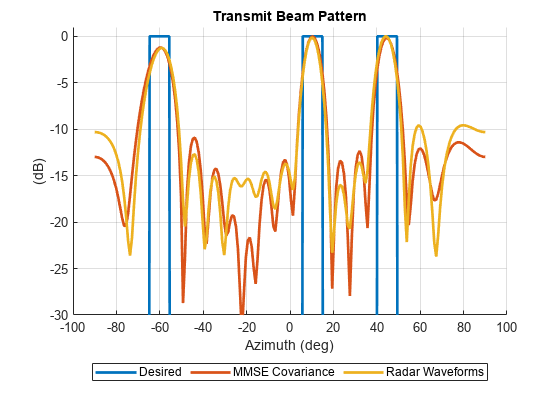

figure
hold on
plot(ang, pow2db(Bdes + eps), 'LineWidth', 2)
plot(ang, pow2db(Bmmse/max(Bmmse)), 'LineWidth', 2)
plot(ang, pow2db(Bca/max(Bca)), 'LineWidth', 2)

grid on
xlabel('Azimuth (deg)')
ylabel('(dB)')
legend('Desired', 'MMSE Covariance', 'Radar Waveforms', 'Location', 'southoutside', 'Orientation', 'horizontal')
ylim([-30 1])
title('Transmit Beam Pattern')

The waveforms synthesized by CA form a beam pattern close to the beam pattern produced by `Rmmse`. Some distortion is present, but the main lobes are mostly undistorted. Since the diagonal elements of `Rmmse` were constraint to be equal to $\frac{P_t}{N}$, the synthesized waveforms `Xca` must have average power equal to 0.5e6/16=31250 watt. Verify that the defined low PAR constraint is satisfied for all synthesized waveforms.

% Average power
Pn = diag(Rca);

% Peak-to-average power ratio
PARn = max(abs(Xca).^2, [], 2)./Pn;

array2table([Pn.'; PARn.'], 'VariableNames', compose('%d', 1:N), 'RowNames', {'Average Power', 'Peak-to-Average Power Ratio'})

ans = 2x16 table
                                     1        2        3        4        5        6        7        8        9       10       11       12       13       14       15       16  
                                   _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

    Average Power                  31250    31250    31250    31250  

To verify that the generated waveforms have low range sidelobes (an important requirement for a good radar waveform), plot the autocorrelation function for one of the waveforms in `Xca`.

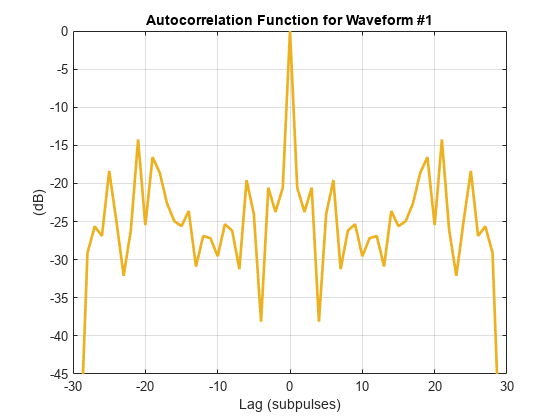

% Plot the autocorrelation function for the nth waveform in Xca
n = 1;
[acmag_ca, delay] = ambgfun(Xca(n, :), 1, 1/M, "Cut", "Doppler");

figure;
ax = gca;
colors = ax.ColorOrder;
plot(delay, mag2db(acmag_ca), 'Color', colors(3, :), 'Linewidth', 2)
xlabel('Lag (subpulses)')
ylabel('(dB)')
title(sprintf('Autocorrelation Function for Waveform #%d', n))
grid on;
ylim([-45 0]);

The range sidelobes for the generated waveforms are on the order of or lower than -13 dB, which is the sidelobe level of a rectangular LFM pulse.

## Radar-Communication Waveform Synthesis

The RadCom system uses the same waveforms for joint radar and communication. If ${\bf H}$ is a known channel matrix and ${\bf X}$ is a matrix containing transmitted waveforms, the signal received by the downlink users is a product ${\bf H}{\bf X}$. One way to design a set of dual-function waveforms is to embed the communication symbols into the radar waveforms such that the received signal ${\bf H}{\bf X}$ is as close as possible to the set of the desired communication symbols ${\bf S}$. In other words, such that the difference ${\bf HX}-{\bf S}\$ is minimized. This difference is known as the multi-user interference (MUI). 

A set of suitable waveforms is a solution to the following trade-off objective function with two terms: the first term is the MUI, while the second term represents the mismatch between the desired and the resulting beam pattern


$$\min_{\bf X} \rho\|{\bf HX}-{\bf S}\|_F^2 + (1-\rho)\|{\bf X}-{\bf X}_0\|_F^2$$


s.t. $\frac{1}{L}diag({\bf XX}^H)=\frac{P_t}{N}{\bf 1}$

here ${\bf X}_0$ is the initial set of radar waveforms that form the desired beam pattern and $\rho$ is a parameter controlling the trade-off between the radar and the communication function. Again, the constraint in this optimization problem guarantees that all antenna elements transmit equal power, and the total power is equal to $P_t$.

If $\rho$ is close to zero, the obtained waveforms will be as close as possible to the initial radar waveforms guaranteeing a good radar performance. However, the MUI in this case can be high resulting in a poor communication performance. When $\rho$ is close to one, the MUI minimization is prioritized resulting in a good communication performance, but possibly poor radar performance. In this case the resulting waveforms might diverge significantly from the initial radar waveforms and therefore the resulting beam pattern might be significantly different from the desired beam pattern.

Authors in [5] use the Riemannian Conjugate Gradient (RCG) method to solve the trade-off optimization and find a set of dual-function waveforms. Use the `helperRadComWaveform` helper function that implements the RCG method to embed the 4-by-30 set of QPSK symbols `S` into the set of synthesized radar waveforms `Xca` using the generated 4-by-16 channel matrix `H`.

% Radar-communication trade-off parameter
rho = 0.4;

% Use RCG to embed the communication symbols in S into the waveforms in Xca
% assuming known channel matrix H.
Xradcom = helperRadComWaveform(H, S, Xca, Pt, rho);

% Compute the corresponding waveform covariance matrix and the transmit beam pattern
Rradcom = Xradcom*Xradcom'/M;
Bradcom = abs(diag(A'*Rradcom*A))/(4*pi);

Compare the beam pattern formed by the obtained waveforms `Xradcom `against the desired beam pattern `Pdes`, the beam pattern obtained using the optimal covariance matrix `Rmmse`, and the beam pattern formed by the radar waveforms `Xca` generated by CA.

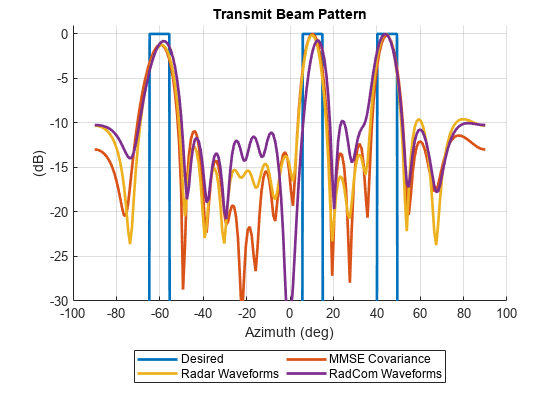

figure;
hold on;
plot(ang, pow2db(Bdes + eps), 'LineWidth', 2);
plot(ang, pow2db(Bmmse/max(Bmmse)), 'LineWidth', 2);
plot(ang, pow2db(Bca/max(Bca)), 'LineWidth', 2);
plot(ang, pow2db(Bradcom/max(Bradcom)), 'LineWidth', 2);

grid on;
xlabel('Azimuth (deg)');
ylabel('(dB)');
legend('Desired', 'MMSE Covariance', 'Radar Waveforms', 'RadCom Waveforms',...
    'Location', 'southoutside', 'Orientation', 'horizontal', 'NumColumns', 2)
ylim([-30 1])
title('Transmit Beam Pattern')

Embedding communication data into the radar waveform causes some transmit beam pattern distortion, however the main lobes are not affected in a significant way. To show the effect of MUI minimization compare the autocorrelation functions of a dual-function waveform in `Xradcom` and its radar counterpart from `Xca`.

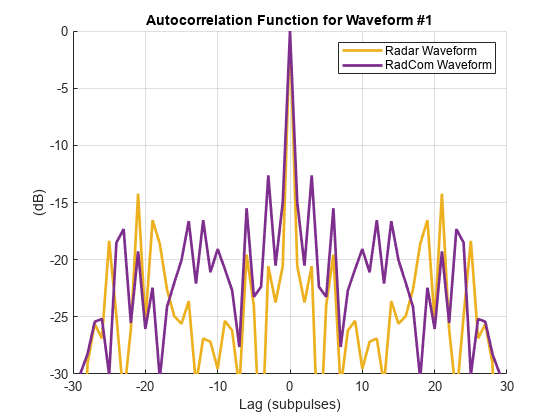

[acmag_rc, delay] = ambgfun(Xradcom(n, :), 1, 1/M, "Cut", "Doppler");

figure
ax = gca;
colors = ax.ColorOrder;

hold on;
plot(delay, mag2db(acmag_ca), 'Color', colors(3, :), 'LineWidth', 2)
plot(delay, mag2db(acmag_rc), 'Color', colors(4, :), 'LineWidth', 2)
xlabel('Lag (subpulses)')
ylabel('(dB)')
title(sprintf('Autocorrelation Function for Waveform #%d', n))
grid on;
ylim([-30 0]);

legend('Radar Waveform', 'RadCom Waveform');

It is evident that after embedding the communication information into the radar waveform the close range sidelobes have increased. The overall peak-to-sidelobe level has not decreased significantly and is still close to 15 dB. The behavior of the sidelobes depends on the value of the parameter $\rho$. In general, increasing $\rho$ results in increased range sidelobes, since more priority is given to the communication function and less to the radar.

## Joint Radar-Communication Simulation

You will use the designed dual-function waveforms to compute a range-angle response and a symbol error rate. Assume that the RadCom system is located at the origin. Let the duration of each subpulse be $\tau$=0.25$\mu$s. This means that the bandwidth of the system is $B=1/\tau$=4 MHz. Let the pulse repetition frequency be equal to 15 KHz.

tau = 5e-7;                         % Subpulse duration
B = 1/tau;                          % Bandwidth
prf = 15e3;                         % PRF
fs = B;                             % Sample rate

% The RadCom system is located at the origin and is not moving
radcompos = [0; 0; 0];
radcomvel = [0; 0; 0];

From each antenna element of the transmit array transmit a pulse that consists of the corresponding dual-function waveform.

t = 0:1/fs:(1/prf);

waveform = zeros(numel(t), N);
waveform(1:M, :) = Xradcom' / sqrt(Pt/N);

transmitter = phased.Transmitter('Gain', 0, 'PeakPower', Pt/N, 'InUseOutputPort', true);
txsig = zeros(size(waveform));
for n = 1:N
    txsig(:, n) = transmitter(waveform(:, n));
end

Radiate the transmitted pulses and propagate them towards the targets through a free space channel.

% Positions of the targets of interest in Cartesian coordinates
[x, y, z] = sph2cart(deg2rad(tgtAz), zeros(size(tgtAz)), tgtRng);
tgtpos = [x; y; z];

% Assume the targets are static
tgtvel = zeros(3, numel(tgtAz));

% Calculate the target angles as seen from the transmit array
[tgtRng, tgtang] = rangeangle(tgtpos, radcompos);

radiator = phased.Radiator('Sensor', array, 'OperatingFrequency', fc, 'CombineRadiatedSignals', true);
radtxsig = radiator(txsig, tgtang);

channel = phased.FreeSpace('SampleRate', fs, 'TwoWayPropagation', true, 'OperatingFrequency',fc);
radtxsig = channel(radtxsig, radcompos, tgtpos, radcomvel, tgtvel);

Reflect the transmitted pulses off the targets and receive the reflected echoes by the receive array. 

% Target radar cross sections
tgtRCS = [2.7 3.1 4.3];

% Reflect pulse off targets
target = phased.RadarTarget('Model', 'Nonfluctuating', 'MeanRCS', tgtRCS, 'OperatingFrequency', fc);
tgtsig = target(radtxsig);

% Receive target returns at the receive array
collector = phased.Collector('Sensor', array, 'OperatingFrequency', fc);
rxsig = collector(tgtsig, tgtang);

receiver = phased.ReceiverPreamp('Gain', 0, 'NoiseFigure', 2.7, 'SampleRate', fs);
rxsig = receiver(rxsig);

Process the received pulses by computing the range-angle response.

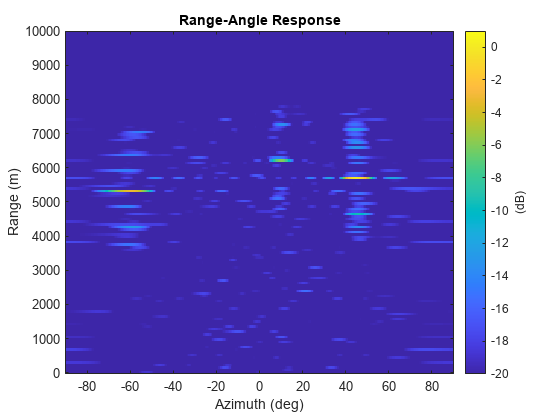

% Compute range-angle response
rngangresp = phased.RangeAngleResponse(...
    'SensorArray',array,'OperatingFrequency',fc,...
    'SampleRate',fs,'PropagationSpeed',collector.PropagationSpeed);

resp = zeros(numel(t), rngangresp.NumAngleSamples, N);

% Apply matched filter N times. One time for each waveform. Then integrate
% the results.
for i = 1:N
    [resp(:, :, i), rng_grid, ang_grid] = rngangresp(rxsig, flipud(Xradcom(i, :).'));
end

% Plot the range angle response
figure
resp_int = sum(abs(resp).^2, 3);
resp_max = max(resp_int, [], 'all');
imagesc(ang_grid, rng_grid, pow2db(resp_int/resp_max))
clim([-20 1])
axis xy
xlabel('Azimuth (deg)')
ylabel('Range (m)')
title('Range-Angle Response')
cbar = colorbar;
cbar.Label.String = '(dB)';

All three targets of interest are visible on the range-angle response. Now, transmit the dual-function waveforms through the MIMO scattering channel `H` and compute the resulting error rate.

rd = pskdemod(H*Xradcom, Q, pi/Q);
[numErr, errRatio] = symerr(data, rd)

numErr = 6

errRatio = 0.0500

The error rate is close to 4.2%. Note that the resulting performance heavily depends on the trade-off parameter $\rho$. To show this for different values of $\rho$ compute the symbol error rate, the peak-to-sidelobe level ratio of the range response (averaged over `N` waveforms), and the beam pattern mismatch between `Xca` and `Xradcom.`

% Vary the radar-communication trade-off parameter from 0 to 1
rho = 0.0:0.1:1;

er = zeros(size(rho));
psl = zeros(size(rho));
bpmm = zeros(size(rho));

for i = 1:numel(rho)
    Xrc = helperRadComWaveform(H, S, Xca, Pt, rho(i));

    % Transmit through the communication channel and compute the error
    % rate
    rd = pskdemod(H*Xrc, Q, pi/Q);
    [~, er(i)] = symerr(data, rd);

    % Compute the peak to sidelobe level ratio
    psl(i) = helperAveragePSL(Xrc);
    
    % Compute the beam pattern
    Rrc = Xrc*Xrc'/M;
    Brc = abs(diag(A'*Rrc*A))/(4*pi);

    % Mismatch between the beam pattern produced by the radar waveforms Xca
    % and the RadCom waveforms Xrc
    bpmm(i) = sqrt(trapz(deg2rad(ang), (Bca - Brc).^2.*cosd(ang).'/(2*pi)));
end

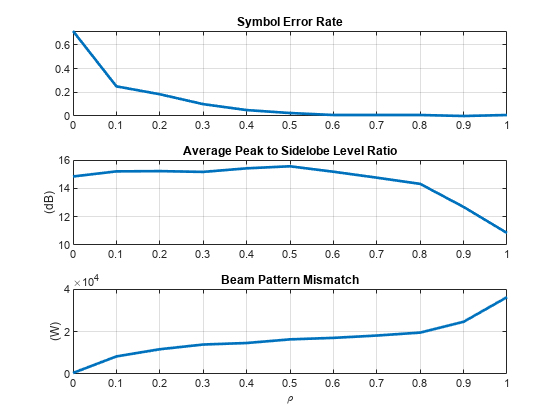

figure;
tiledlayout(3, 1);

ax = nexttile;
plot(rho, er, 'LineWidth', 2);
grid on;
title('Symbol Error Rate');

nexttile;
plot(rho, psl, 'LineWidth', 2);
ylabel('(dB)');
grid on;
title('Average Peak to Sidelobe Level Ratio');

nexttile;
plot(rho, bpmm, 'LineWidth', 2);
grid on;
ylabel('(W)');
title('Beam Pattern Mismatch');

xlabel('\rho');

Increasing $\rho$ decreases the symbol error rate but results in the higher sidelobes and the deterioration of the transmit beam pattern.

## Conclusions

This example shows how to design a set of dual-function waveforms for a joint MIMO RadCom system. The resulting waveforms must form a desired beam pattern to steer transmit beams towards multiple radar targets of interest and transmit a desired symbol matrix to the downlink users over a known MIMO channel. First, the example shows how to synthesize a set of radar waveforms that produce the desired transmit beam pattern. Then, the communication symbols are embedded into the synthesized radar waveforms such that the multi-user interference and the distortions in the transmit beam pattern are minimized. The example then simulates a transmission of the designed waveforms and computes the resulting range-angle response and symbol error rate. 

## References

- Martone, Anthony, and Moeness Amin. "A view on radar and communication systems coexistence and dual functionality in the era of spectrum sensing." *Digital Signal Processing* 119 (2021): 103135.

- Fuhrmann, Daniel R., and Geoffrey San Antonio. "Transmit beamforming for MIMO radar systems using signal cross-correlation." *IEEE Transactions on Aerospace and Electronic Systems* 44, no. 1 (2008): 171-186

- Stoica, Petre, Jian Li, and Xumin Zhu. "Waveform synthesis for diversity-based transmit beampattern design." *IEEE Transactions on Signal Processing* 56, no. 6 (2008): 2593-2598.

- He, Hao, Jian Li, and Petre Stoica. *Waveform design for active sensing systems: a computational approach*. Cambridge University Press, 2012.

- Liu, Fan, Longfei Zhou, Christos Masouros, Ang Li, Wu Luo, and Athina Petropulu. "Toward dual-functional radar-communication systems: Optimal waveform design." *IEEE Transactions on Signal Processing* 66, no. 16 (2018): 4264-4279.

## Supporting Functions

type 'helperMMSECovariance.m'

function R = helperMMSECovariance(elPos, Pdesired, ang)
% This function computes a waveform covariance matrix that generates a
% desired transmit beam pattern. The computation is based on the squared
% error optimization described in 
%
% Fuhrmann, Daniel R., and Geoffrey San Antonio. "Transmit beamforming for
% MIMO radar systems using signal cross-correlation." IEEE Transactions on
% Aerospace and Electronic Systems 44, no. 1 (2008): 171-186.
%
% elPos is a 3-by-N matrix of array element positions normalized by the
% wavelength. Pdesired is the desired beam pattern evaluated at the angles
% specified in ang.

N = size(elPos, 2);

% Initial covariance is random. x_ is a vector of all elements that are
% in the upper triangular part of the matrix above the main diagonal.
x_ = initialCovariance(N);

% Normalized the desired beam pattern such that the total transmit power is
% equal to the number of array elements N.
Pdesired = N * Pdesired / (2*pi*trapz(deg2rad(ang), Pdesired.*cosd(ang)

type 'helperCAWaveformSynthesis.m'

function X = helperCAWaveformSynthesis(R, M, rho)
% This function generates a set of waveforms that form the desired
% covariance matrix R. M is the number of waveform samples and rho is a
% parameter controlling the resulting peak-to-average power ratio (PAR).
% This algorithm is described in the chapter 14 of
%
% He, Hao, Jian Li, and Petre Stoica. Waveform design for active sensing
% systems: a computational approach. Cambridge University Press, 2012.
%
% and in
%
% Stoica, Petre, Jian Li, and Xumin Zhu. "Waveform synthesis for
% diversity-based transmit beampattern design." IEEE Transactions on Signal
% Processing 56, no. 6 (2008): 2593-2598.

N = size(R, 1);
epsilon = 0.1;

% P can control the autocorrelation level for each waveform. If P = M the
% optimization is trying to minimize sidelobes for across all M-1 lags.
P = M;

% Arbitrary semi-unitary matrix
U = (randn(P + M - 1, N*P) + 1i*randn(P + M - 1, N*P))/sqrt(2);

% Expended covariance is used to minimize the autocorrelation

type 'helperRadComWaveform.m'

function X = helperRadComWaveform(H, S, X0, Pt, rho)
% This function implements Riemannian Conjugate Gradient (RCG) algorithm
% described in 
%
% Liu, Fan, Longfei Zhou, Christos Masouros, Ang Li, Wu Luo, and Athina
% Petropulu. "Toward dual-functional radar-communication systems: Optimal
% waveform design." IEEE Transactions on Signal Processing 66, no. 16
% (2018): 4264-4279.
%
% H is a K-by-N channel matrix where K is the number of down-link users
% and N is the number of antennas at the RadCom base station. S is a K-by-L
% symbol matrix, where L is the number of symbols. X0 is a N-by-L matrix of
% waveforms that generate the desired radar beam pattern. Pt is total
% transmit power, and rho is a trade-off parameter to balance the radar and
% communication performance.

delta = 1e-6;
maxNumIterations = 500;

[N, M] = size(X0);
S = S * sqrt(Pt/size(S, 1));

A = [sqrt(rho)*H; sqrt(1-rho)*eye(N)];
B = [sqrt(rho)*S; sqrt(1-rho)*X0];

X = (randn(N, M) + 1i*randn(N, M))/sqrt(2);
X = Rx(X, 

type 'helperAveragePSL.m'

function avpsl = helperAveragePSL(X)
    [n, m] = size(X);
    psl = zeros(n, 1);

    for i = 1:n
        acmag = ambgfun(X(i, :), 1, 1/m, "Cut", "Doppler");
        psl(i) = acmag(m)/max([acmag(1:m-1) acmag(m+1:end)]);
    end

    avpsl = mag2db(mean(psl));
end


Copyright 2022 The MathWorks, Inc.